# A multivariate brain signature for reward

Speer et al. 2023, Neuroimage

[https://www.sciencedirect.com/science/article/pii/S1053811923001362?via%3Dihub](https://www.sciencedirect.com/science/article/pii/S1053811923001362?via%3Dihub)

See also: The signature map on Open Science Foundation:

[https://osf.io/q3x7r](https://osf.io/q3x7r)

This script loads and plots the signature weights, and shows an example of how to calculate signature response (or 'pattern expression') for a new test dataset.

% Start in this folder: 2023_Speer_Brain_Reward_Signature_BRS

obj = fmri_data('Reward_Signature_bootstrapped_0.5.nii.gz');

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.025223 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 1616  Bit rate: 10.66 bits


d = descriptives(obj);

 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 1616  Bit rate: 10.66 bits
  Images missing >10% of voxels:   0	
Voxels: 242953	Nonempty (1+ images have valid data): 1615	Complete  (all images have data): 1615
Unique data values: 1615
 
Min: -4.910	Max: 9.377	Mean: 3.225	Std: 2.837
 
    Percentiles    Values 
    ___________    _______

        0.1        -4.8285
        0.5        -4.5706
          1        -4.4018
          5        -3.6593
         25         3.4291
         50          3.872
         75         4.5333
         95         6.0039
         99         7.3926
       99.5          8

## Plots of slices and surfaces

SPM12: spm_check_registration (v7759)              09:15:01 - 23/03/2023
Display /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels: 127 regions
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


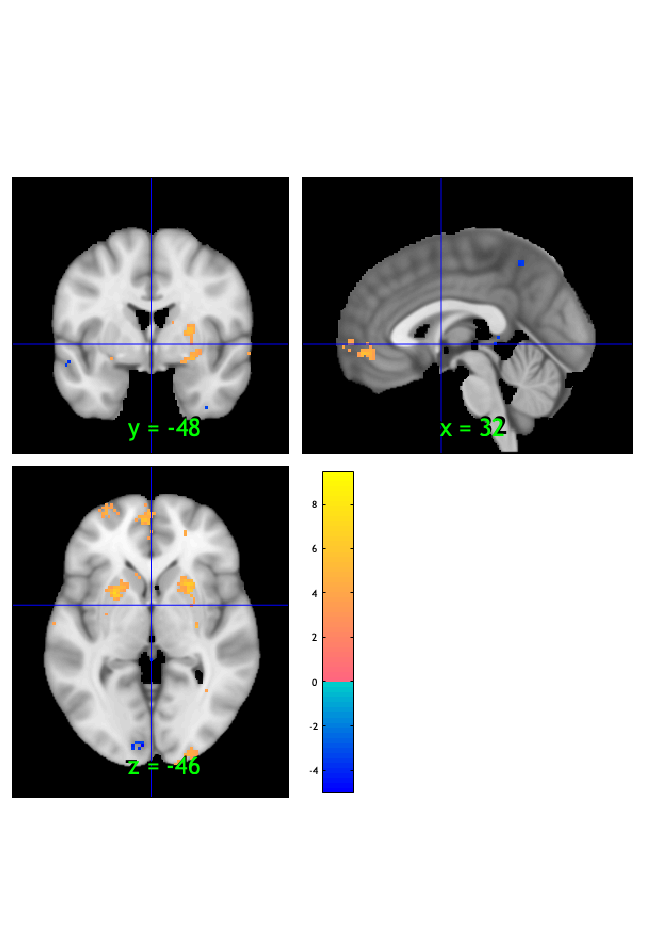

orthviews(obj);

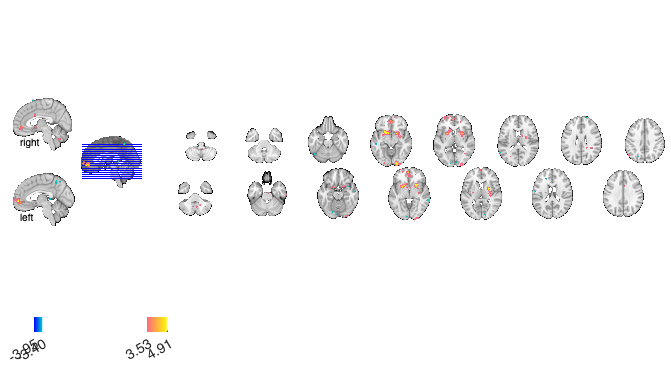

Setting up fmridisplay objects
sagittal montage:  46 voxels displayed, 1569 not displayed on these slices
sagittal montage:  27 voxels displayed, 1588 not displayed on these slices
sagittal montage:  32 voxels displayed, 1583 not displayed on these slices
axial montage: 225 voxels displayed, 1390 not displayed on these slices
axial montage: 323 voxels displayed, 1292 not displayed on these slices


create_figure('montage'); 
axis off
montage(obj);

create_figure('surfaces', 1, 2);
surface(obj);

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


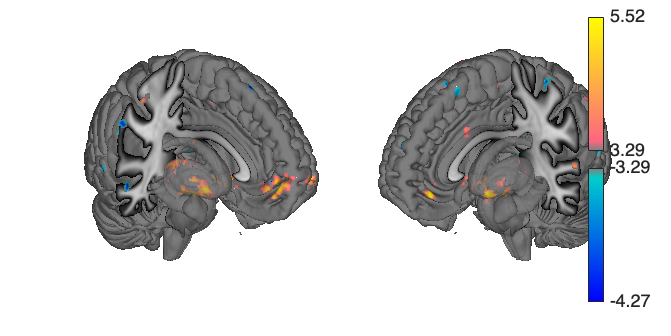

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


subplot(1, 2, 2);
surface(obj, 'right_cutaway');

## Labeling regions and showing labeled regions in tables and slices 

% Choose regions with >10 contiguous voxels for display
sum(cat(1, reg.numVox) > 10)

ans = 10


reg = region(obj);

Grouping contiguous voxels: 127 regions


reg = reg(cat(1, reg.numVox) > 10);

[regp regn] = table(reg, 'nolegend');

____________________________________________________________________________________________________________________________________________
Positive Effects
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
         Region         Volume           XYZ            maxZ      modal_label_descriptions      Perc_covered_by_label    Atlas_regions_covered    region_index
    ________________    ______    _________________    ______    ___________________________    _____________________  

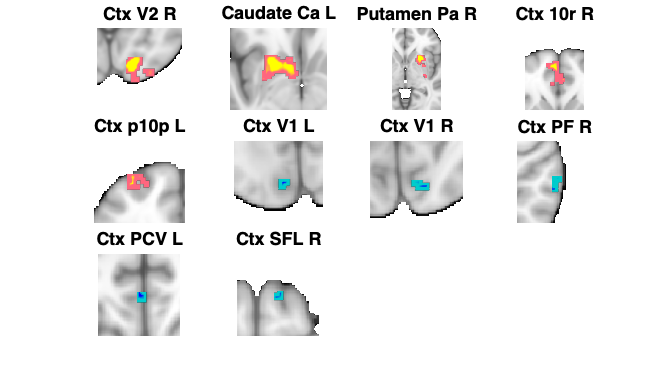


% Montage of regions with labels
montage([regp regn], 'regioncenters', 'colormap');

drawnow, snapnow


## Applying the signature to a new test dataset

To apply the signature to a new dataset, you can use apply_mask() method in CANlab tools, with the 'pattern_expression' keyword option to apply the signature as a weight mask rather than a binary mask.

The test dataset here is a standard emotion-regulation demo dataset included with CANlab tools. It was chosen because it's packaged with the tools for demonstration purposes, not because we expect it to have any meaningful relationship with the reward signature.

test_images = load_image_set('emotionreg');

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/Can

sig_response = apply_mask(test_images, obj, 'pattern_expression');
sig_response

sig_response = 1.0e+03 *

    0.8160
    0.1820
    0.1848
   -0.1269
   -0.7354
    1.2115
    0.5205
   -0.2402
   -0.1475
   -0.3187


ttest(sig_response)

ans = 0


% Test whether expression values are different from zero.
% This is just a demo - be careful about making inferences from this, as
% these signatures often have intercept values that are ignored and not
% stored in the image. This will affect the zero-point in potentially
% arbitrary ways.
[h, p, ci, stats] = ttest(sig_response)  

h = 0

p = 0.6594

ci =  -187.6431
  292.0855


stats = struct with fields:
    tstat: 0.4453
       df: 29
       sd: 642.3684
